%run code with matlab as a livescript
%if error "package is missing" occurs, run "pkg load control" in command window

s = tf('s');

%remove example and insert your transferfct
G = 12/(4 *(2*s+1)*((5/4) * s +1) )

G =
 
         12
  -----------------
  10 s^2 + 13 s + 4
 
Continuous-time transfer function.



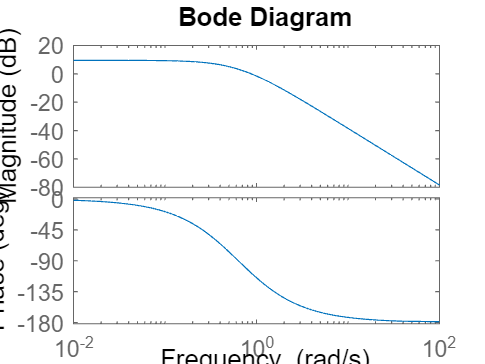


opts = bodeoptions('cstprefs');
opts.PhaseWrapping='on';
bode(G, opts)


%plots
G_fb = feedback(G,1)

G_fb =
 
          12
  ------------------
  10 s^2 + 13 s + 16
 
Continuous-time transfer function.



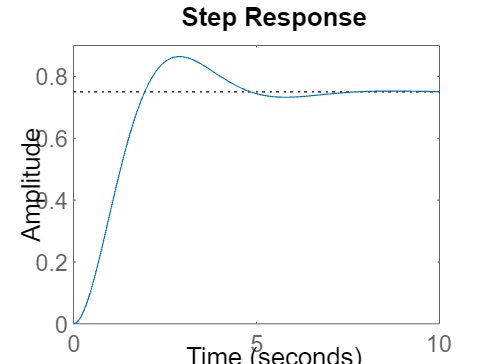

step(G_fb)

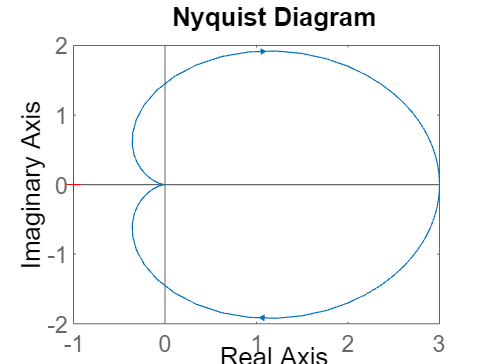

nyquist(G)

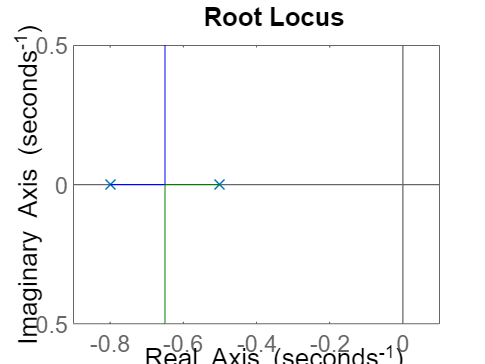

rlocus(G)

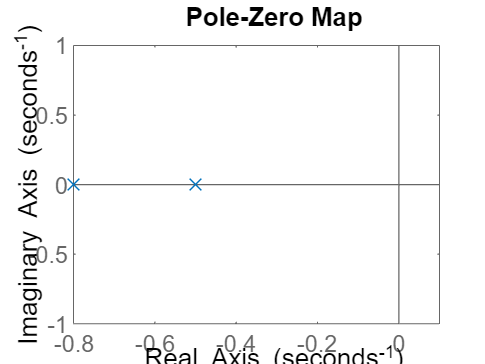

pzmap(G)


%values
damp(G)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -5.00e-01     1.00e+00       5.00e-01         2.00e+00    
 -8.00e-01     1.00e+00       8.00e-01         1.25e+00    


zero(G)


ans =

  0×1 empty double column vector

